clc
clear

% % Discrete time
% syms ts
g = 9.81;
% 
% Ad = [1 ts;
%      0 1]
% Bd = [-(g*ts^2)/2 0;
%      -g*ts 0]
% Cd = Ad
% Dd = Bd
% % Dsys = ss(Ad,Bd,Cd,Dd)
% Dcont = [Bd(:,1) Ad*Bd(:,1)]
% rank(Dcont)
% Dobs = [Cd;
%         Cd*Ad]
% rank(Dobs)
% Continous
Ac = [0 1 0 0;
      0 0 0 0;
      0 0 0 1;
      0 0 0 0]

Ac =      0     1     0     0
     0     0     0     0
     0     0     0     1
     0     0     0     0


Bc = [0 0;
     -g 0;
      0 0;
      0 -g]

Bc =          0         0
   -9.8100         0
         0         0
         0   -9.8100


Cc = eye(4)

Cc =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Dc = zeros([4,2])

Dc =      0     0
     0     0
     0     0
     0     0


Cctrb = [Bc Ac*Bc]

Cctrb =          0         0   -9.8100         0
   -9.8100         0         0         0
         0         0         0   -9.8100
         0   -9.8100         0         0


rank(Cctrb)

ans = 4

Cobs = [Cc;
        Cc*Ac]

Cobs =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
     0     1     0     0
     0     0     0     0
     0     0     0     1
     0     0     0     0


rank(Cobs)

ans = 4

sysC = ss(Ac,Bc,Cc,Dc);

%% LQR implementation

Q = eye(4);
Q(1,1) = 1/(.1016^2);
Q(3,3) = 1/(.1016^2);
R = eye(2);
max_u = pi/24

max_u = 0.1309

R(1,1) = 1/(max_u)^2;
R(2,2) = 1/(max_u)^2;
[K, s, e] = lqr(sysC,Q,R,zeros([4,2]))

K =    -1.2884   -0.5290         0         0
         0         0   -1.2884   -0.5290


s =    39.7734    7.6648         0         0
    7.6648    3.1469         0         0
         0         0   39.7734    7.6648
         0         0    7.6648    3.1469


e =   -2.5946 + 2.4305i
  -2.5946 - 2.4305i
  -2.5946 + 2.4305i
  -2.5946 - 2.4305i


sysCL = ss([Ac-Bc*K],Bc,Cc,zeros([4,2]))


sysCL =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  -12.64  -5.189       0       0
   x3       0       0       0       1
   x4       0       0  -12.64  -5.189
 
  B = 
          u1     u2
   x1      0      0
   x2  -9.81      0
   x3      0      0
   x4      0  -9.81
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.



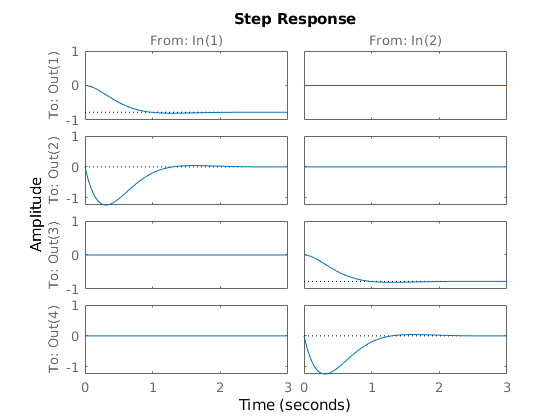

step(sysCL)